# PROF. AMBROSINO R.___ESAME___11/03/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## DEFINIZIONI

#### Variabili Simboliche 

syms q1 q2 dq1 dq2 ddq1 ddq2 u1 u2 w real

#### Parametri

m1 = 1.0;
m2 = 1.2;
k1 = 20;
k2 = 25;
c1 = 1; 
c2 = 1.2;
k = 12;
c = 0.8;
k3 = 40;

#### Ingresso-Stato-Uscita

% Ingresso
u = [u1;
     u2];

% Stato
x = [q1;
     q2;
     dq1;
     dq2];

% Uscita
y = [q1;
     q2];

n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico Non Lineare

eq1_sym = m1*ddq1 == -k1*q1 -c1*dq1 +k*(q2-q1) +k3*(q2-q1)^3 +c*(dq2-dq1) +u1;
eq2_sym = m2*ddq2 == -k2*q2 -c2*dq2 -k*(q2-q1) -k3*(q2-q1)^3 -c*(dq2-dq1) +u2;

eqs_sym = [eq1_sym;
           eq2_sym];

sol = solve(eqs_sym, [ddq1, ddq2], "ReturnConditions",true);

% dx/dt
f = [dq1;
     dq2;
     sol.ddq1;
     sol.ddq2];

% y
g = y;

## PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### Punti di Equilibrio

eq1_peql = subs(eq1_sym, {ddq1, ddq2, dq1, dq2, u1, u2}, {0, 0, 0, 0, 0, 0});
eq2_peql = subs(eq2_sym, {ddq1, ddq2, dq1, dq2, u1, u2}, {0, 0, 0, 0, 0, 0});

eqs_peql = [eq1_peql;
            eq2_peql];

peql = solve(eqs_peql, [q1, q2], "ReturnConditions", true);

x1_star = double(peql.q1);
x2_star = double(peql.q2);

x_peql = [x1_star;
          x2_star]

x_peql =      0
     0


#### Punto di Equilibrio corrispondente a u1* = 1 N e u2* = -0.5 N

u1_star = 1;
u2_star = -0.5;

u_star = [u1_star;
          u2_star];

eq1_peql = subs(eq1_sym, {ddq1, ddq2, dq1, dq2, u1, u2}, {0, 0, 0, 0, u1_star, u2_star});
eq2_peql = subs(eq2_sym, {ddq1, ddq2, dq1, dq2, u1, u2}, {0, 0, 0, 0, u1_star, u2_star});

eqs_peql = [eq1_peql;
            eq2_peql];

peql = solve(eqs_peql, [q1, q2], "ReturnConditions", true);

x1_star = double(peql.q1);
x2_star = double(peql.q2);

x_star = [x1_star;
          x2_star;
          0;
          0]

x_star =     0.0298
   -0.0038
         0
         0


#### Modello Linearizzato attorno a x*

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_star; u_star]));
B = double(subs(B_sym, [x; u], [x_star; u_star]));
C = double(subs(C_sym, [x; u], [x_star; u_star]));
D = double(subs(D_sym, [x; u], [x_star; u_star]));

sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -32.14   12.14    -1.8     0.8
   x4   10.11  -30.95  0.6667  -1.667
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       1       0
   x4       0  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Verifica Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


#### Verifica Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## ASSEGNAMENTO DEGLI AUTOVALORI

#### Specifiche

delta = 0.0000001;
eig_des = [-5, -5+delta, -10, -10+delta];

q10 = 0.1;
q20 = 0.3;

x0_eig = [q10;
          q20;
          0;
          0];

q1_ref = 0.5;
q2_ref = 1;

r = [q1_ref;
     q2_ref];

#### Sintesi

K_eig = place(A, B, eig_des);
eig(A-B*K_eig)

ans =    -5.0000
  -10.0000
   -5.0000
  -10.0000


#### Compensazione del guadagno

sys_cl_eig = ss((A-B*K_eig), B, C, D);
cl_gain_eig = dcgain(sys_cl_eig);
N = pinv(cl_gain_eig);

#### Verifica Simulazione

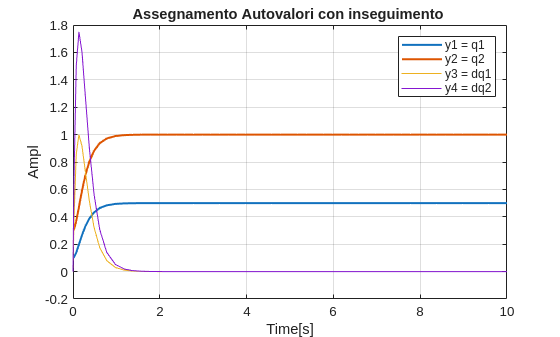

% Plot MATLAB
out = sim('Verifica_EIG_11032026_es.slx');
y1 = out.y1.Data;
y2 = out.y2.Data;
y3 = out.y3.Data;
y4 = out.y4.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
hold on
plot(time, y2, "LineWidth", 1.5);
hold on
plot(time, y3, "LineWidth", 0.2);
hold on
plot(time, y4, "LineWidth", 0.2);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = q1', 'y2 = q2', 'y3 = dq1', 'y4 = dq2');
title('Assegnamento Autovalori con inseguimento ');

## CONTROLLO H-INF

#### Modello con Disturbo

eq1_sym = m1*ddq1 == -k1*q1 -c1*dq1 +k*(q2-q1) +k3*(q2-q1)^3 +c*(dq2-dq1) +u1 +w;

eqs_sym = [eq1_sym;
           eq2_sym];

sol = solve(eqs_sym, [ddq1, ddq2], "ReturnConditions",true);

% dx/dt
f_w = [dq1;
       dq2;
       sol.ddq1;
       sol.ddq2];

#### Impianto Generalizzato

% ingresso generalizzato
u_gen = [w;
         u];

% uscita di prestazione
rho = 0.1;
z = [y;
     rho*u];

% uscita generalizzata
y_gen = [z;
         y];

g_w = y_gen;

#### Modello con Disturbo Linearizzato attorno a (x*,u*)

A_w_sym = jacobian(f_w, x);
B_u_sym = jacobian(f_w, u);
B_w_sym = jacobian(f_w, w);
C_w_sym = jacobian(g_w, x);
D_w_sym = jacobian(g_w, u);

A_w = double(subs(A_w_sym, [x; u], [x_star; u_star]));
B_u = double(subs(B_u_sym, [x; u], [x_star; u_star]));
B_w = double(subs(B_w_sym, [x; u], [x_star; u_star]));
C_w = double(subs(C_w_sym, [x; u], [x_star; u_star]));
D_w = double(subs(D_w_sym, [x; u], [x_star; u_star]));

sys_gen = ss(A_w, [B_w B_u], C_w, [D_w zeros(6,1)])


sys_gen =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -32.14   12.14    -1.8     0.8
   x4   10.11  -30.95  0.6667  -1.667
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3       1       1       0
   x4       0       0  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   0   0
   y4   0   0   0   0
   y5   1   0   0   0
   y6   0   1   0   0
 
  D = 
        u1   u2   u3
   y1    0    0    0
   y2    0    0    0
   y3  0.1    0    0
   y4    0  0.1    0
   y5    0    0    0
   y6    0    0    0
 
Continuous-time state-space model.


if(~(isstable(sys_gen)))
    disp('sistema generalizzato fonte di instabilità');
end

appost


#### Sintesi H-inf

[K_hinf, ~, gamma] = hinfsyn(sys_gen, p, m);
gamma

gamma = 0.1135

if(~(isstable(K_hinf)))
    disp('sistema LTI K-inf fonte di instabilità');
end

appost


#### Verifica Simulazione

out = sim("Verifica_HINF_11032026.slx");

Found algebraic loop that contains: 
Verifica_HINF_11032026/LTI System2/Internal
Verifica_HINF_11032026/LTI System2/Internal
Verifica_HINF_11032026/Sum1 (algebraic variable)


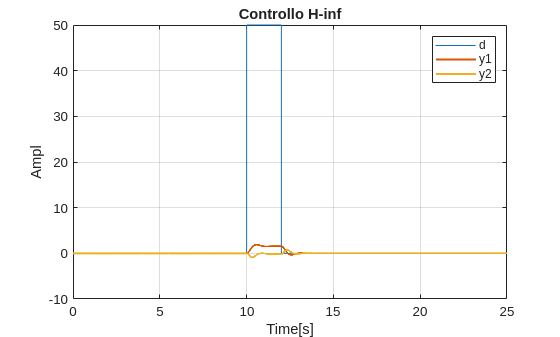

y1_hinf = out.y1_hinf.Data;
y2_hinf = out.y2_hinf.Data;
y1_nohinf = out.y1.Data;
y2_nohinf = out.y2.Data;
d = out.d.Data;
time = out.y1_hinf.Time;

% Plot 
figure
plot(time, d, "LineWidth", 0.2);
grid on
hold on
plot(time, y1_hinf, "LineWidth", 1.5);
plot(time, y2_hinf, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('d', 'y1', 'y2');
title('Controllo H-inf');

hold off

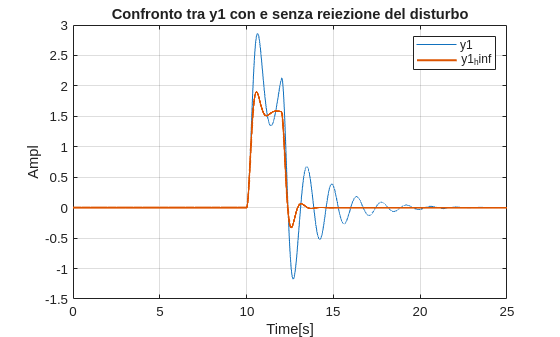

plot(time, y1_nohinf, "LineWidth", 0.1);
grid on
hold on
plot(time, y1_hinf, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1', 'y1_hinf');
title('Confronto tra y1 con e senza reiezione del disturbo');

hold off

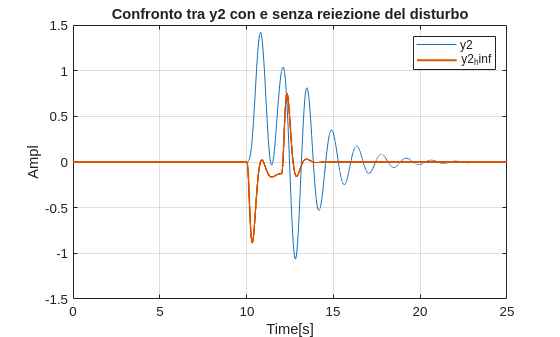

plot(time, y2_nohinf, "LineWidth", 0.1);
grid on
hold on
plot(time, y2_hinf, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y2', 'y2_hinf')
title('Confronto tra y2 con e senza reiezione del disturbo');

#### Schema Simulink completo consultabile in:

#### [Verifica_Hinf](matlab:open_system('Verifica_HINF_11032026.slx'))